clc;
clear;

load("xy_out_sensor_r53_degree5_kg10100_mesh_1_0.2_0.2_0.5.mat")

x = -2:0.25:2;
y = -2:0.25:2;
[X Y] = meshgrid(x,y);

fig1 = figure

fig1 =   Figure (11) - 속성 있음:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  모든 속성 표시


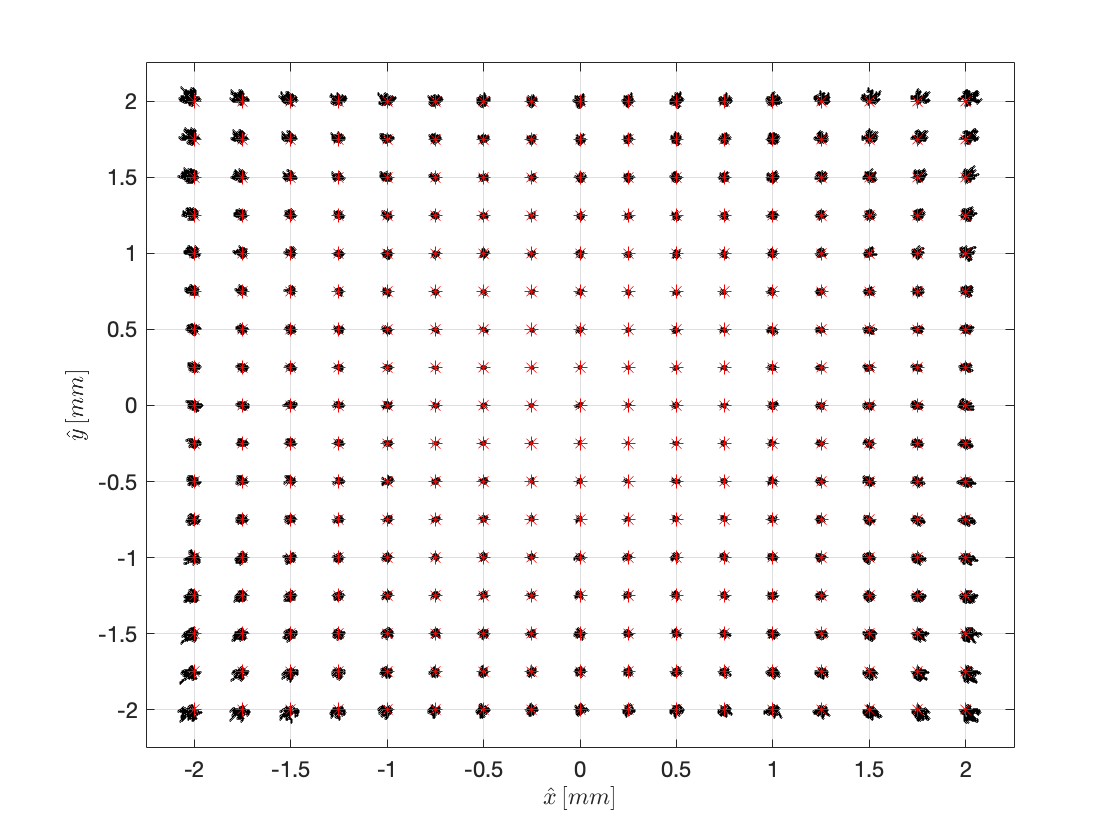

scatter(x_total_out,y_total_out,1,'black')
hold on
scatter(X,Y,30,'red','*')
grid on
xlim([-2.25 2.25])
ylim([-2.25 2.25])
box on

ylatex = '$\hat{y}\,[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\hat{x}\,[mm]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig1,'xy_out_r53_deg5_kg10100_mesh(1,0.2,0.2,0.5).png')

x1_hat = x_total_out(1,170000*8+1:170000*9);
x1_hat = x1_hat(1,120001:130000);
y0_hat = y_total_out(1,170000*8+1:170000*9);
y0_hat = y0_hat(1,120001:130000);

ww = linspace(0,360,10000);


fig2 = figure

fig2 =   Figure (12) - 속성 있음:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  모든 속성 표시


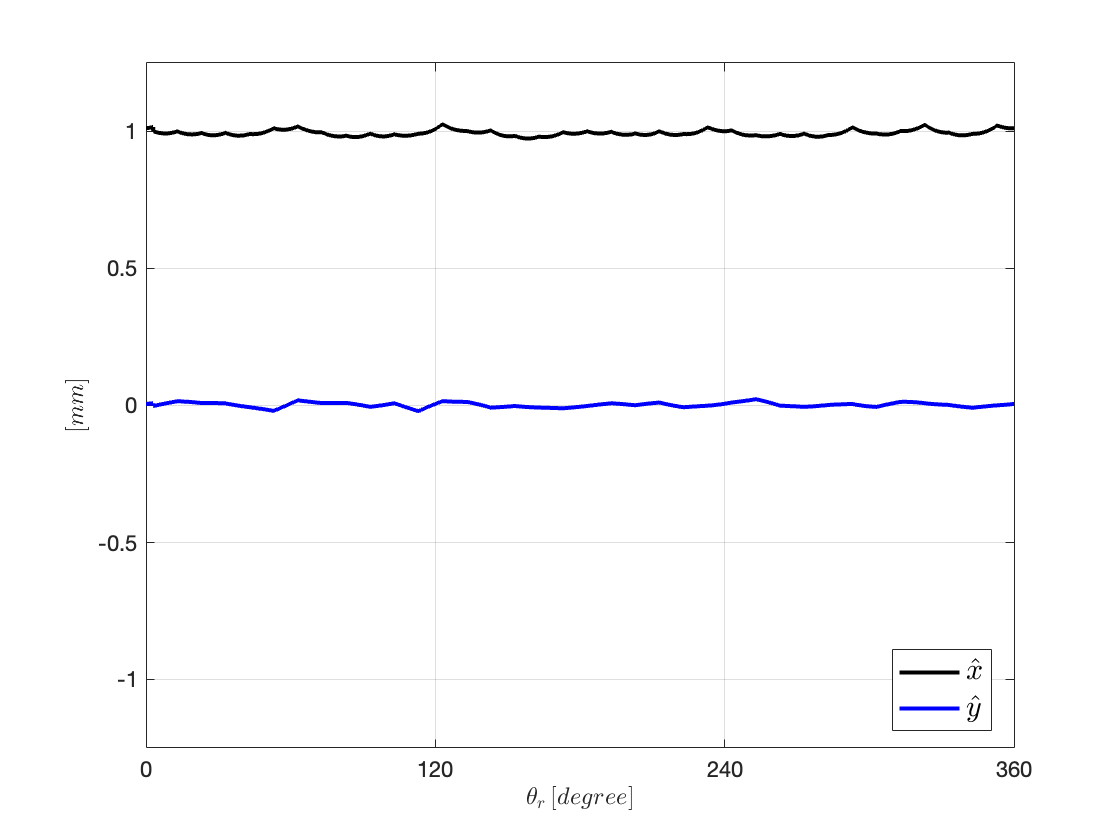

hold on
plot(ww,x1_hat,'k','Linewidth',2)
plot(ww,y0_hat,'b','Linewidth',2)
leg1 = legend('$\hat{x}$','$\hat{y}$','Location','best');
set(leg1, 'Interpreter', 'latex');
set(leg1, 'FontSize', 15);
grid on
box on
xlim([0 360])
xticks([0 120 240 360])
ylim([-1.25 1.25])
ylatex = '$[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\theta_r\,[degree]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig2,'x1y0_r53_deg5_kg10100_mesh(1,0.2,0.2,0.5).png')

% theta_one_period = theta_out(1,1:10000)

theta_one_period =    -0.6963   -0.6866   -0.6672   -0.6478   -0.6284   -0.6090   -0.5993   -0.5800   -0.5606   -0.5412   -0.5218   -0.5121   -0.4927   -0.4732   -0.4538   -0.4344   -0.4247   -0.4053   -0.3859   -0.3665   -0.3470   -0.3373   -0.3179   -0.2985   -0.2790   -0.2596   -0.2499   -0.2304   -0.2110   -0.1915   -0.1721   -0.1624   -0.1429   -0.1234   -0.1040   -0.0845   -0.0748   -0.0553   -0.0359   -0.0164    0.0031    0.0128    0.0323    0.0518    0.0713    0.0907    0.1005    0.1200    0.1395    0.1590


% thetatheta = linspace(1,2*pi,length(theta_one_period))

thetatheta =     1.0000    1.0005    1.0011    1.0016    1.0021    1.0026    1.0032    1.0037    1.0042    1.0048    1.0053    1.0058    1.0063    1.0069    1.0074    1.0079    1.0085    1.0090    1.0095    1.0100    1.0106    1.0111    1.0116    1.0122    1.0127    1.0132    1.0137    1.0143    1.0148    1.0153    1.0159    1.0164    1.0169    1.0174    1.0180    1.0185    1.0190    1.0195    1.0201    1.0206    1.0211    1.0217    1.0222    1.0227    1.0232    1.0238    1.0243    1.0248    1.0254    1.0259


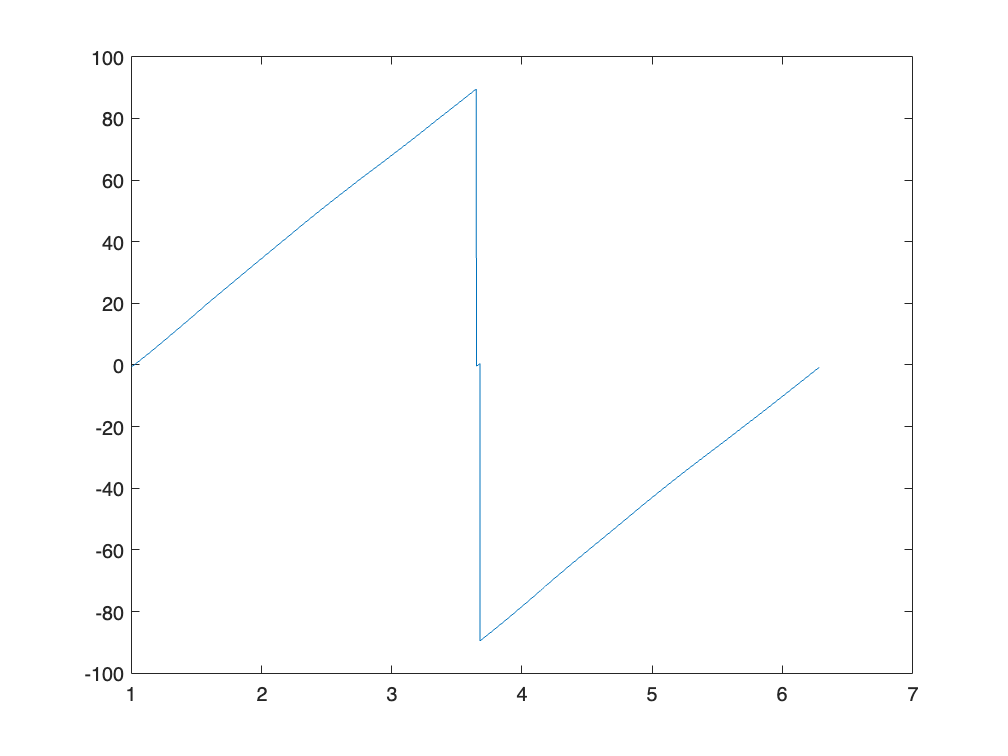

% figure
% plot(thetatheta,theta_one_period)

clc;
clear;

load("xy_out_sensor_r48_degree5_kg4250_mesh_1_0.2_0.2_0.5.mat")

x = -1.5:0.5:1.5;
y = -1.5:0.5:1.5;
[X Y] = meshgrid(x,y);

fig3 = figure;

fig3 =   Figure (8) - 속성 있음:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  모든 속성 표시


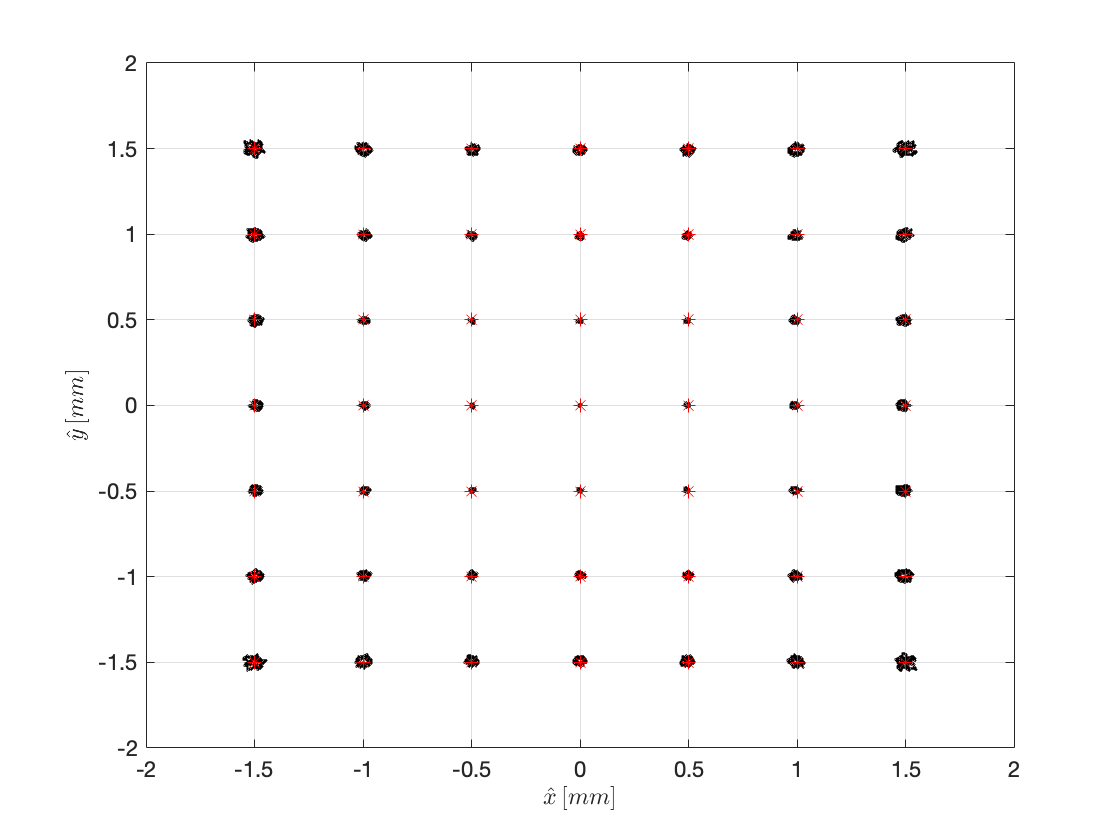

scatter(x_total_out,y_total_out,1,'black')
hold on
scatter(X,Y,30,'red','*')
grid on
xlim([-2 2])
ylim([-2 2])
box on

ylatex = '$\hat{y}\,[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\hat{x}\,[mm]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig3,'xy_out_r48_deg5_kg4250_mesh(1,0.2,0.2,0.5).png')

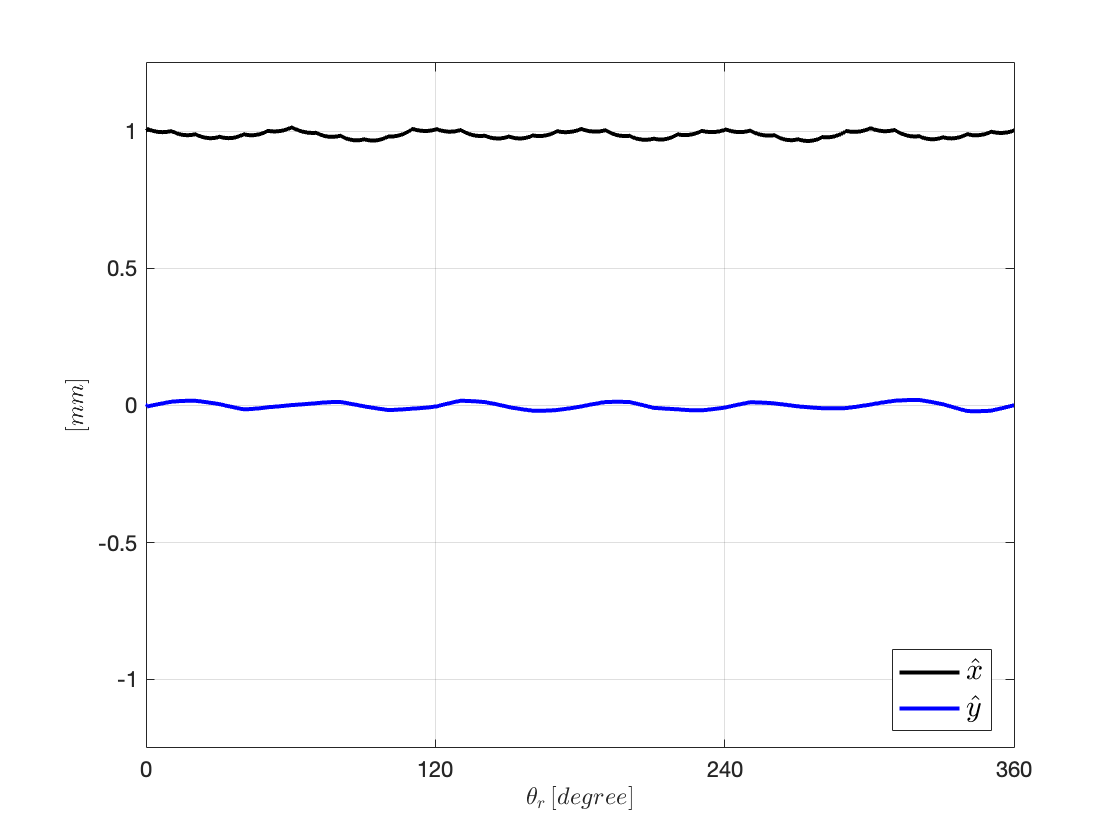

x1_hat = x_total_out(1,210001:280000);
x1_hat = x1_hat(1,50001:60000);
y0_hat = y_total_out(1,210001:280000);
y0_hat = y0_hat(1,50001:60000);

ww = linspace(0,360,length(y0_hat));


fig4 = figure;
hold on
plot(ww,x1_hat,'k','Linewidth',2)
plot(ww,y0_hat,'b','Linewidth',2)
leg1 = legend('$\hat{x}$','$\hat{y}$','Location','best');
set(leg1, 'Interpreter', 'latex');
set(leg1, 'FontSize', 15);
grid on
box on
xlim([0 360])
xticks([0 120 240 360])
ylim([-1.25 1.25])
ylatex = '$[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\theta_r\,[degree]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig4,'x1y0_r48_deg5_kg4250_mesh(1,0.2,0.2,0.5).png')

clc;
clear;

load("xy_out_sensor_r43_degree5_kg1750_mesh_a_0.2_0.2_a.mat")

x = -1.5:0.5:1.5;
y = -1.5:0.5:1.5;
[X Y] = meshgrid(x,y);

fig5 = figure;

fig5 =   Figure (6) - 속성 있음:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  모든 속성 표시


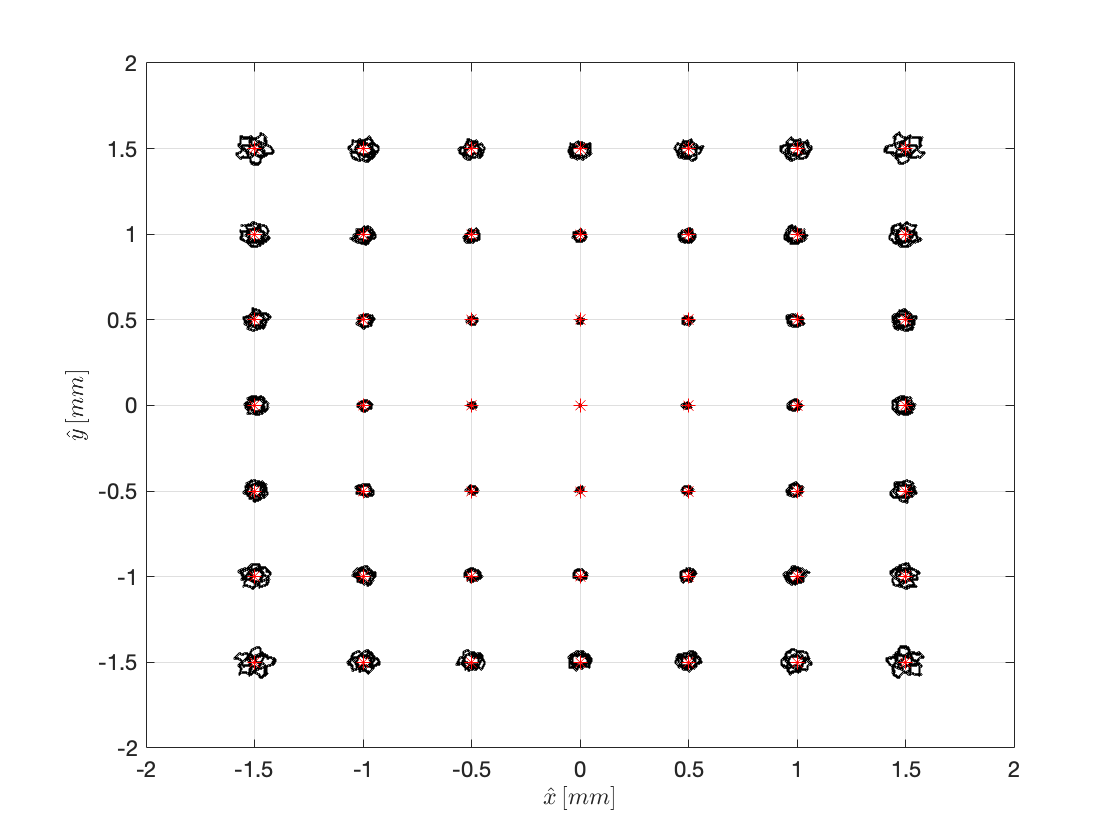

scatter(x_total_out,y_total_out,1,'black')
hold on
scatter(X,Y,30,'red','*')
grid on
xlim([-2 2])
ylim([-2 2])
box on

ylatex = '$\hat{y}\,[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\hat{x}\,[mm]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig5,'xy_out_r43_deg5_kg1750_mesh(a,0.2,0.2,a).png')

x1_hat = x_total_out(1,210001:280000);
x1_hat = x1_hat(1,50001:60000);
y0_hat = y_total_out(1,210001:280000);
y0_hat = y0_hat(1,50001:60000);

ww = linspace(0,360,length(y0_hat));


fig6 = figure;

fig6 =   Figure (7) - 속성 있음:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  모든 속성 표시


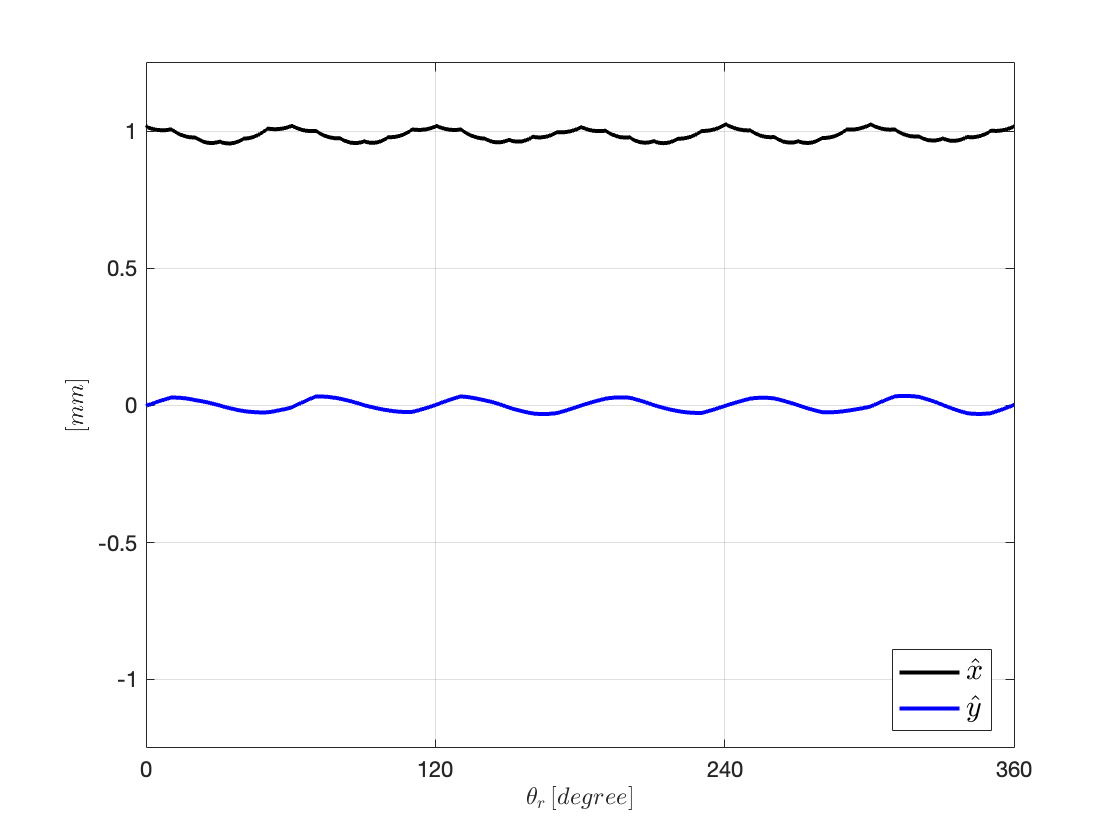

hold on
plot(ww,x1_hat,'k','Linewidth',2)
plot(ww,y0_hat,'b','Linewidth',2)
leg1 = legend('$\hat{x}$','$\hat{y}$','Location','best');
set(leg1, 'Interpreter', 'latex');
set(leg1, 'FontSize', 15);
grid on
box on
xlim([0 360])
xticks([0 120 240 360])
ylim([-1.25 1.25])
ylatex = '$[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\theta_r\,[degree]$';
xlabel(xlatex,'Interpreter','latex')
hold off

saveas(fig6,'x1y0_r43_deg5_kg1750_mesh(a,0.2,0.2,a).png')